% circle trajectory
ang = 0:0.02:2*pi;
zL = 0:0.02:2.5;
cx = [zeros(1,length(zL)),2.5+2.5*cos(ang)];
cy = [zeros(1,length(zL)),2.5*sin(ang)];
cz = [zL,zeros(1,length(ang))+2.5];


==========================

5B - No noise

==========================

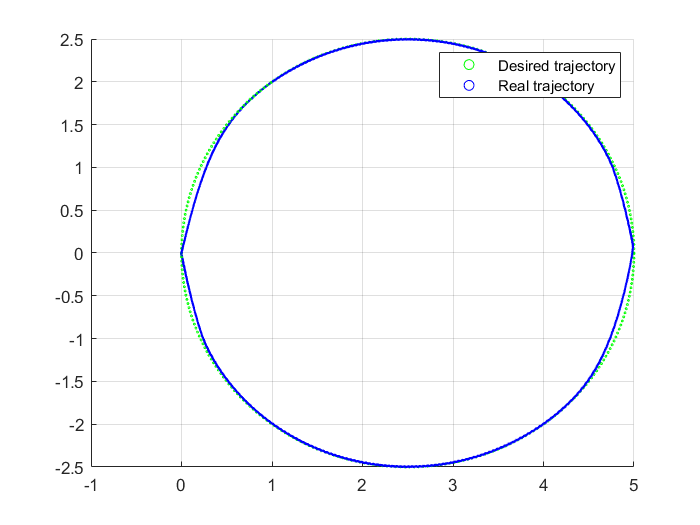

figure;
hold on;
scatter3(cx,cy,cz,2,'g');
scatter3(drones.LogOutput(1,:),drones.LogOutput(2,:),drones.LogOutput(3,:),1,'blue');
legend('Desired trajectory','Real trajectory');
grid on
hold off;

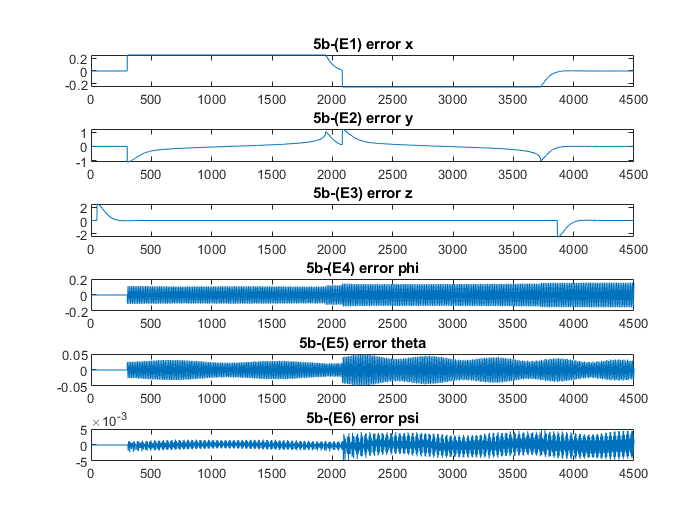

figure;
subplot(6,1,1);
plot(drones.error(1,:));
title('5b-(E1) error x');
subplot(6,1,2);
plot(drones.error(2,:));
title('5b-(E2) error y');
subplot(6,1,3);
plot(drones.error(3,:));
title('5b-(E3) error z');
subplot(6,1,4);
plot(drones.error(4,:));
title('5b-(E4) error phi');
subplot(6,1,5);
plot(drones.error(5,:));
title('5b-(E5) error theta');
subplot(6,1,6);
plot(drones.error(6,:));
title('5b-(E6) error psi');

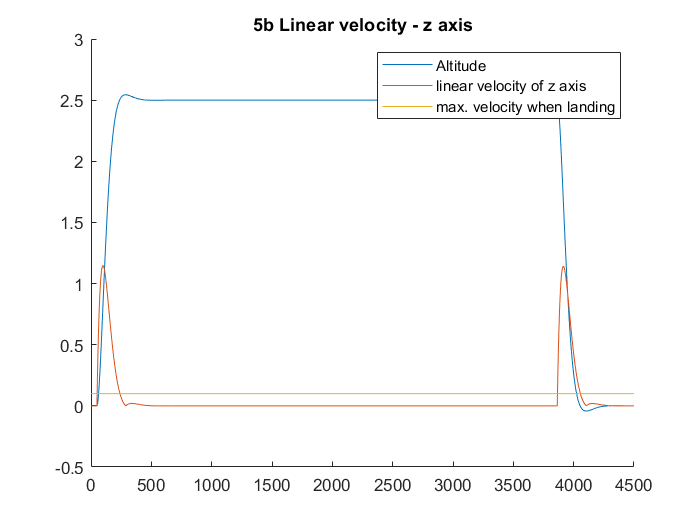

figure;
hold on;
plot(drones.state(3,:));
plot(abs(drones.state(6,:)));
plot(ones(1,length(drones.state(1,:)))*0.1);
legend('Altitude','linear velocity of z axis','max. velocity when landing')
title('5b Linear velocity - z axis');
hold off;

==========================

5C - Noise

==========================

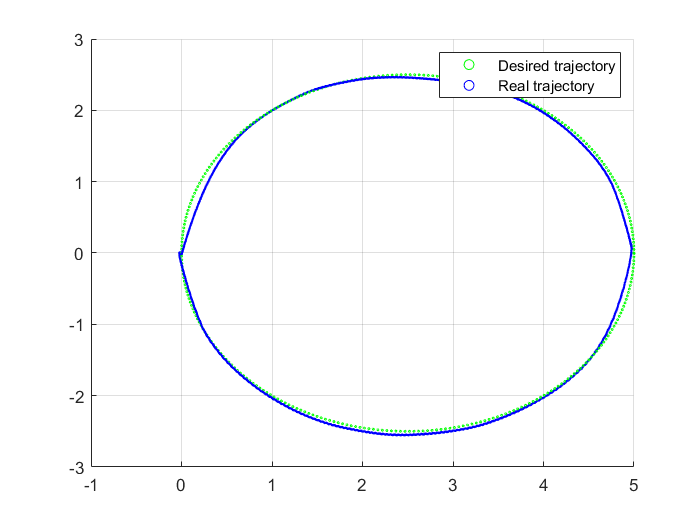

figure;
hold on;
scatter3(cx,cy,cz,2,'g');
scatter3(drones.LogOutput(1,:),drones.LogOutput(2,:),drones.LogOutput(3,:),1,'blue');
legend('Desired trajectory','Real trajectory');
grid on
hold off;

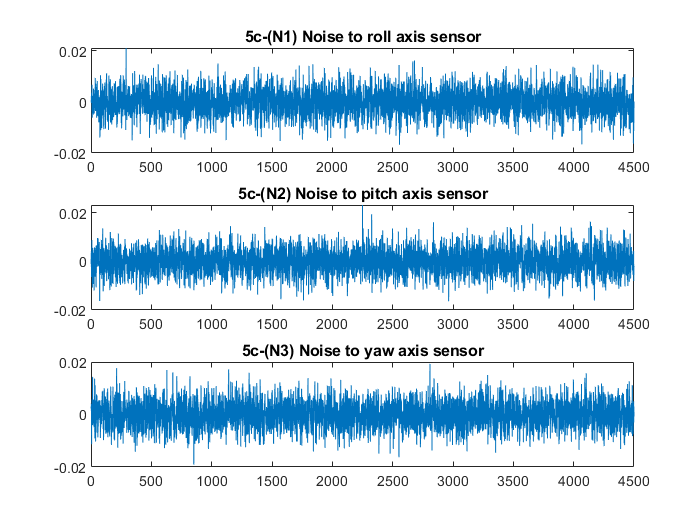

figure;
subplot(3,1,1);
plot(drones.LogNoise(1,:));
title('5c-(N1) Noise to roll axis sensor');
subplot(3,1,2);
plot(drones.LogNoise(2,:));
title('5c-(N2) Noise to pitch axis sensor');
subplot(3,1,3);
plot(drones.LogNoise(3,:));
title('5c-(N3) Noise to yaw axis sensor');

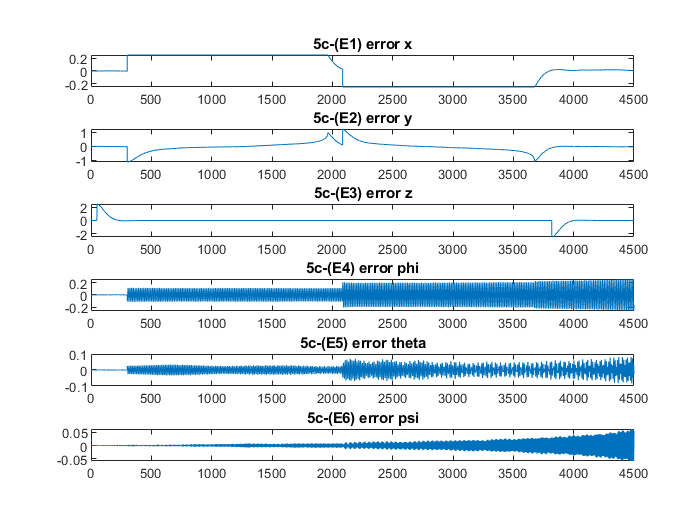

figure;
subplot(6,1,1);
plot(drones.error(1,:));
title('5c-(E1) error x');
subplot(6,1,2);
plot(drones.error(2,:));
title('5c-(E2) error y');
subplot(6,1,3);
plot(drones.error(3,:));
title('5c-(E3) error z');
subplot(6,1,4);
plot(drones.error(4,:));
title('5c-(E4) error phi');
subplot(6,1,5);
plot(drones.error(5,:));
title('5c-(E5) error theta');
subplot(6,1,6);
plot(drones.error(6,:));
title('5c-(E6) error psi');

figure;
hold on;
plot(drones.state(3,:));
plot(abs(drones.state(6,:)));
plot(ones(1,length(drones.state(1,:)))*0.1);
legend('Altitude','linear velocity of z axis','max. velocity when landing')
title('5c Linear velocity - z axis');
hold off;

==========================

5D - Wind

==========================

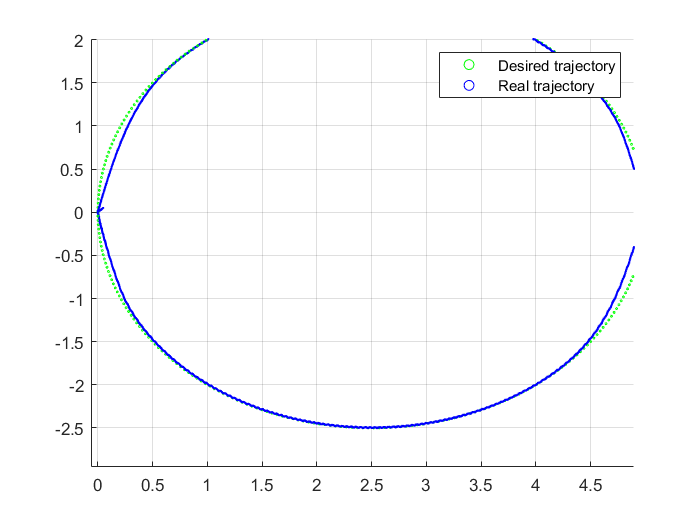

figure;
hold on;
scatter3(cx,cy,cz,2,'g');
scatter3(drones.LogOutput(1,:),drones.LogOutput(2,:),drones.LogOutput(3,:),1,'blue');
legend('Desired trajectory','Real trajectory');
grid on
hold off;

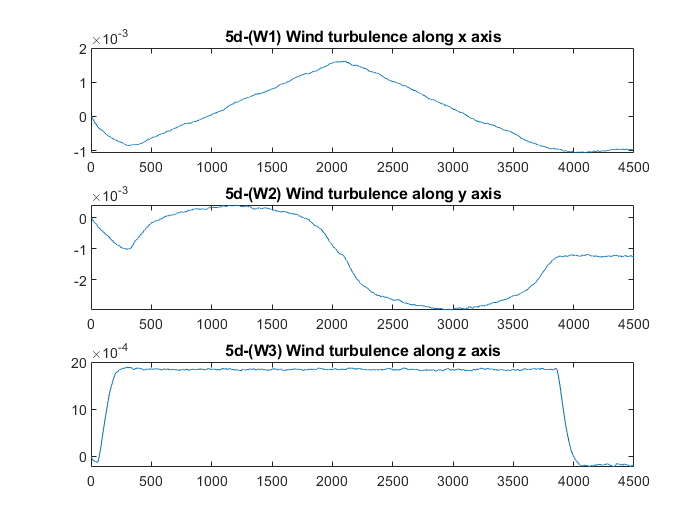

figure;
subplot(3,1,1);
plot(drones.LogWind(1,:));
title('5d-(W1) Wind turbulence along x axis');
subplot(3,1,2);
plot(drones.LogWind(2,:));
title('5d-(W2) Wind turbulence along y axis');
subplot(3,1,3);
plot(drones.LogWind(3,:));
title('5d-(W3) Wind turbulence along z axis');

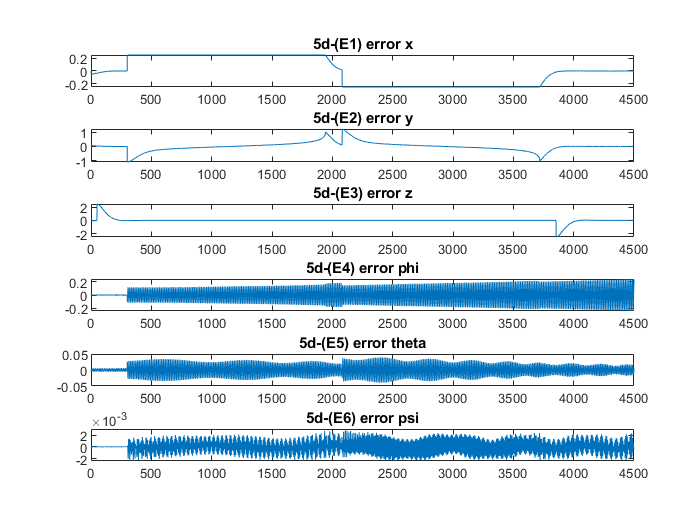

figure;
subplot(6,1,1);
plot(drones.error(1,:));
title('5d-(E1) error x');
subplot(6,1,2);
plot(drones.error(2,:));
title('5d-(E2) error y');
subplot(6,1,3);
plot(drones.error(3,:));
title('5d-(E3) error z');
subplot(6,1,4);
plot(drones.error(4,:));
title('5d-(E4) error phi');
subplot(6,1,5);
plot(drones.error(5,:));
title('5d-(E5) error theta');
subplot(6,1,6);
plot(drones.error(6,:));
title('5d-(E6) error psi');

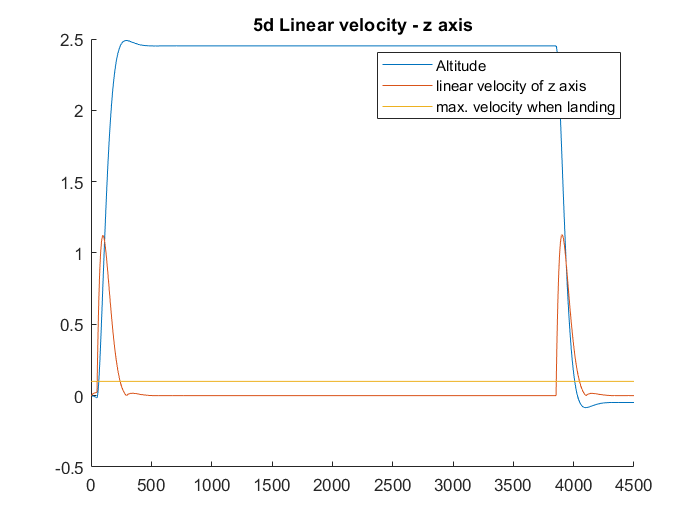

figure;
hold on;
plot(drones.state(3,:));
plot(abs(drones.state(6,:)));
plot(ones(1,length(drones.state(1,:)))*0.1);
legend('Altitude','linear velocity of z axis','max. velocity when landing')
title('5d Linear velocity - z axis');
hold off;

==========================

5E - Multiple drones

==========================

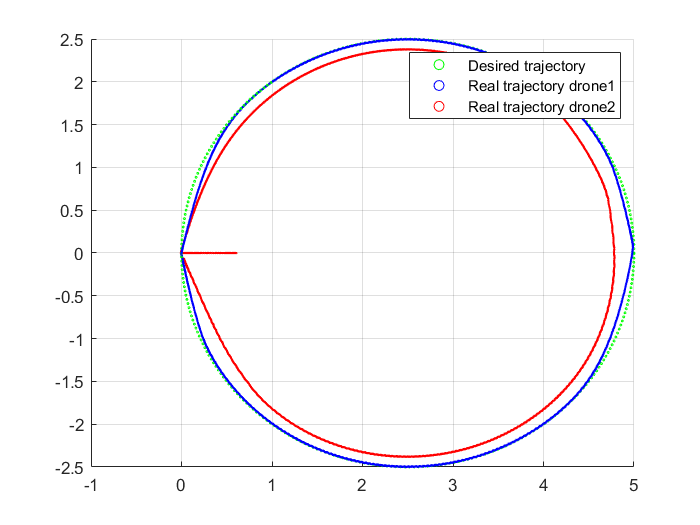

figure;
hold on;
scatter3(cx,cy,cz,2,'g');
scatter3(drones(1).LogOutput(1,:),drones(1).LogOutput(2,:),drones(1).LogOutput(3,:),1,'blue');
scatter3(drones(2).LogOutput(1,:),drones(2).LogOutput(2,:),drones(2).LogOutput(3,:),1,'red');
legend('Desired trajectory','Real trajectory drone1','Real trajectory drone2');
grid on
hold off;

figure
distance = drones(1).LogOutput(1:3,:) - drones(2).LogOutput(1:3,:)

distance =    -0.6000   -0.6000   -0.6002   -0.6004   -0.6007   -0.6011   -0.6015   -0.6019   -0.6023   -0.6026   -0.6028   -0.6029   -0.6028   -0.6027   -0.6026   -0.6026   -0.6025   -0.6026   -0.6028   -0.6031   -0.6034   -0.6037   -0.6041   -0.6043   -0.6045   -0.6045   -0.6045   -0.6043   -0.6041   -0.6040   -0.6039   -0.6038   -0.6039   -0.6041   -0.6043   -0.6046   -0.6049   -0.6051   -0.6053   -0.6053   -0.6052   -0.6051   -0.6049   -0.6046   -0.6045   -0.6043   -0.6043   -0.6044   -0.6046   -0.6048
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

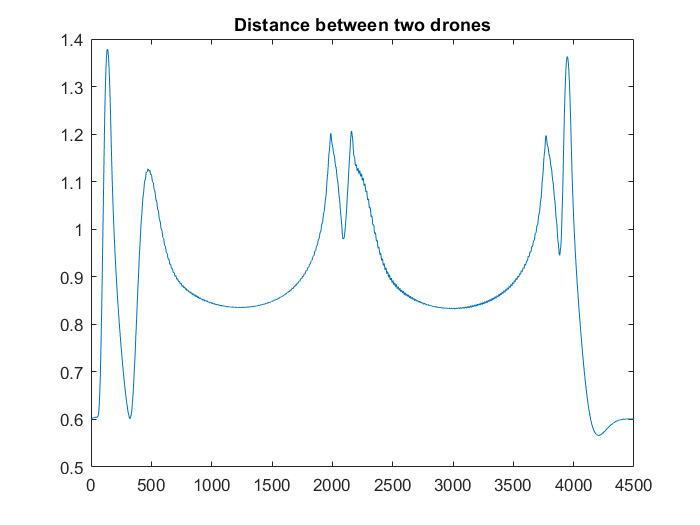

distance = sqrt(sum(distance.^2));
plot(distance);
title('Distance between two drones');

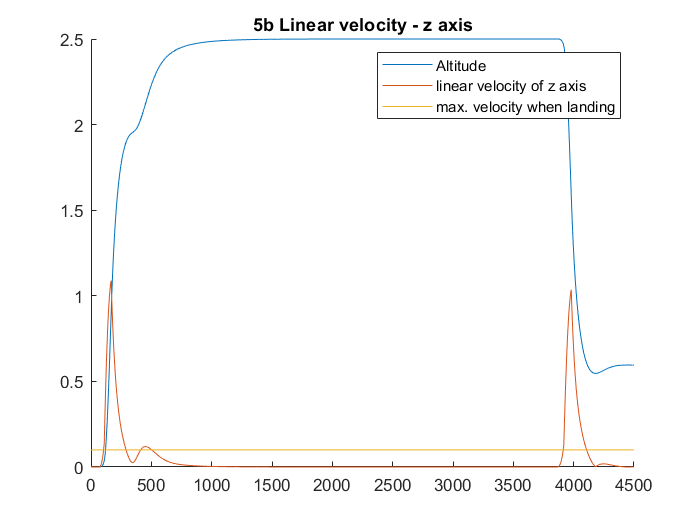

figure;
hold on;
plot(drones(1).state(3,:));
plot(drones(2).state(3,:));
plot(abs(drones(2).state(6,:)));
plot(ones(1,length(drones(2).state(1,:)))*0.1);
legend('Altitude','linear velocity of z axis','max. velocity when landing')
title('5b Linear velocity - z axis');
hold off;